# ED and Eo Calcuations for each month:

## October

a = SolarChart2(1,3).A

a = 390

l = 32;
sigma = 30;
sqm = 112.80;
u = 0.24;
y = 45;

disp("ED AND EO MONTH CALCULATOR");

ED AND EO MONTH CALCULATOR


month = input("Please input a month: [1-12] ");
data = SolarChart2(month,:);
delta = data.DeclinatioNdeg;
et = data.EquationOfTimemin;
a = data.A * 3.2;
b = data.B;
c = data.C;
sunrise = data.AvgSunriseAMMT;

ed = dayEDCalc(l, sigma, y, delta, et, a, b, c, sunrise);
eo =u*ed*sqm;

disp(month + " MONTH ED: " + ed)

5 MONTH ED: 9448.8996


disp(month + " MONTH EO: " + eo)

5 MONTH EO: 255800.6092


## Eo Graph

x = linspace(0,1,6);
%y = [oct_eo, nov_eo, dec_eo, jan_eo, feb_eo, mar_eo];
%plot(x,y)
%xlabel('winter months')
%ylabel('eo')
%title('Eo Graph')

## ADL Graph

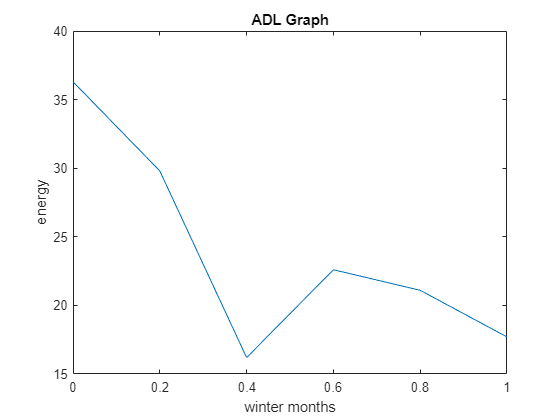

y = [36.3, 29.8, 16.2, 22.6, 21.1, 17.7];
plot(x,y)
xlabel('winter months')
ylabel('energy')
title('ADL Graph')